clearvars; clc;

# Exercitation 3

#### Definitions

s=tf('s');
Gcont=10/(1+s/50);
Ts=0.01;

G=zpk(c2d(Gcont,Ts,'zoh'))


G =
 
    3.9347
  ----------
  (z-0.6065)
 
Sample time: 0.01 seconds
Discrete-time zero/pole/gain model.


#### Disturbance signals

- 
$$\left|y_{\mathrm{d2}}^{\infty } \right|\le 0\ldotp 5$$


$\left|y_{\mathrm{d2}}^{\infty } \right|=\left|\frac{\delta_2 }{K_l }T^2 \right|$, $K_l =\lim_{z\to 1} {\left(z-1\right)}^l C\left(z\right)G\left(z\right)$

[z_G, p_G, k_G]=zpkdata(G,'v');
B=k_G*[1 -z_G];
A=[1 -p_G(1)];

G1=evalfr(G,1)

G1 = 10


$$K_G \ge 0\ldotp 00001$$


2. $\left|y_{\mathrm{d1}}^{\infty } \right|\le 0\ldotp 05$

$\left|y_{\mathrm{d1}}^{\infty } \right|=\left|\frac{\delta_1 }{K_{\mathrm{l2}} }T^2 \right|$, $K_{\mathrm{l2}} =\lim_{z\to 1} {\left(z-1\right)}^{\mathrm{l2}} C\left(z\right)$


$$K_G \ge 0\ldotp 0001$$


#### Transient response

s_hat=0.15;
t_s1=0.8;
zeta=abs(log(s_hat))/(sqrt(pi^2+(log(s_hat))^2));
wn=4.6/(zeta*t_s1);

#### Damping area

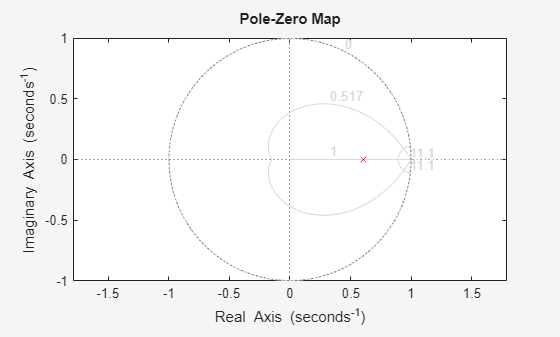

figure;
set(gcf,'Visible','on')
pzmap(G,'r');
axis('equal');
hold on;
zgrid(zeta,wn,Ts);

From the pole-zero map, I can see that I can cancel just one pole (the only pole of G)

A_plus=A;
A_minus=1;
B_plus=1;
B_minus=B;

deg_A=1;

Unrecognized function or variable 'deg'.

deg_B=0;
deg_A_plus=1;
deg_A_minus=0;
deg_B_plus=0;
deb_B_minus=0;